Q3 a.

We now create a simulation of RE Time Series

First, we define the parameters:

lambda = 0.5;
c=1;
rho=0.7;
nu=0.01;

%number of periods
T=100;

Then we create a time series for the iid error terms, e_t (normally distributed here):

e = nu*randn(T,1);

Now we create z based on e:

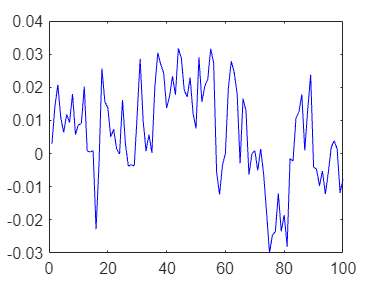

list_z = zeros(T,1);
list_z(1) = [e(1)];
for i=2:T
   z = rho*list_z(i-1)+e(i);
   list_z(i) = z;
end

%Ploting z as blue line
g1 = plot([1:T],list_z,'b');

Q3 b.

Now we create a list for the policy function, y_t(z_t)

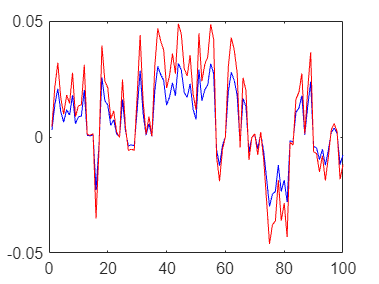

list_y = zeros(T,1);
coef = c/(1-rho*lambda);
for i=1:T
   list_y(i) = coef*list_z(i); 
end

%ploting y with z, as red line
g2 = plot([1:T],list_z,'b', [1:T], list_y,'r');

Q3 c.

Now we plot the response to shock e=0.01:

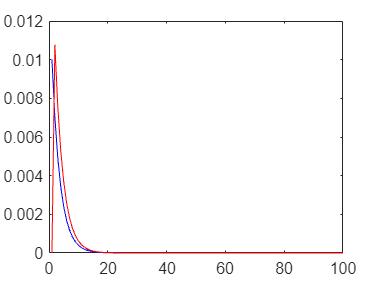

list_e = zeros(T,1);
list_e(1) = 1*nu;

list_z = zeros(T,1);
list_z(1) = [list_e(1)];
list_y = zeros(T,1);
for i=2:T
   z = rho*list_z(i-1)+list_e(i);
   list_z(i) = z;
   list_y(i) = coef*list_z(i);
end

g3 = plot([1:T],list_z,'b', [1:T], list_y,'r');